## Parte 3 - Speech Quantiation 

## Exercício 2.1

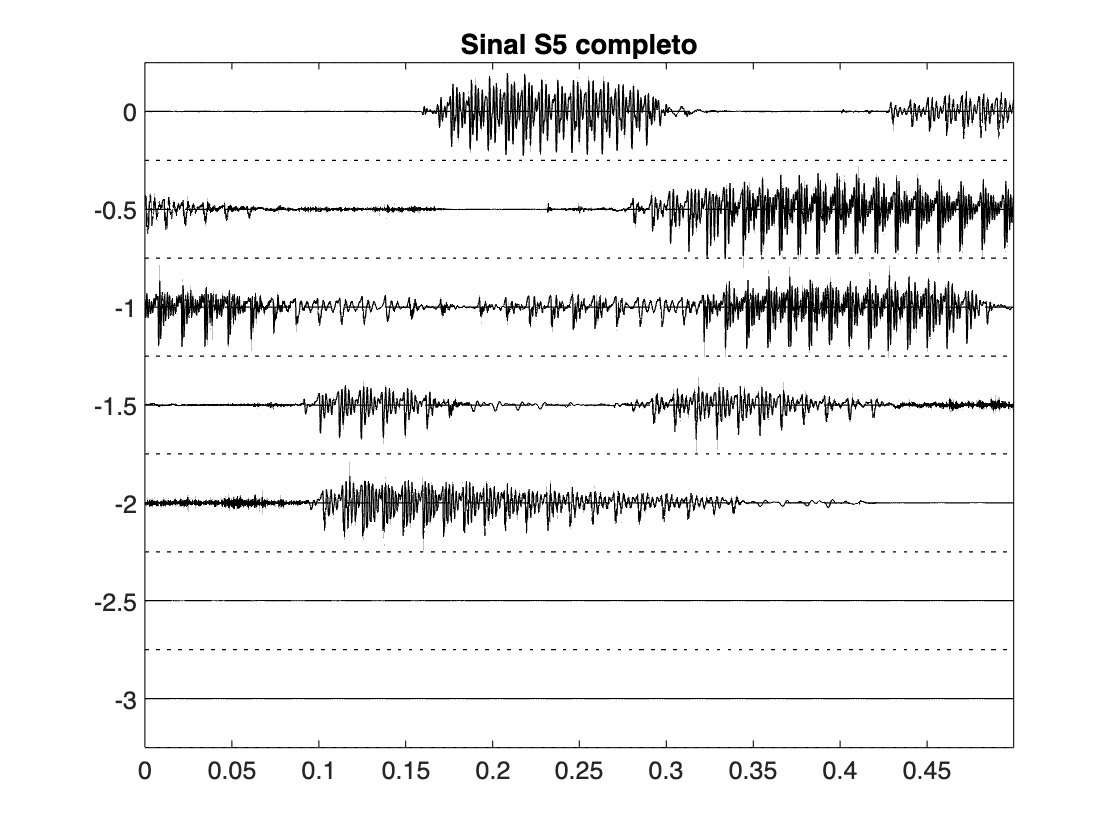

addpath("mcclellan/mcclellan/Functions/")
load("mcclellan/mcclellan/Data/s5.mat");

s5=s5./32768;
striplot(s5,8000,4000);

vetor = s5(1:8000);
title('Sinal S5 completo');

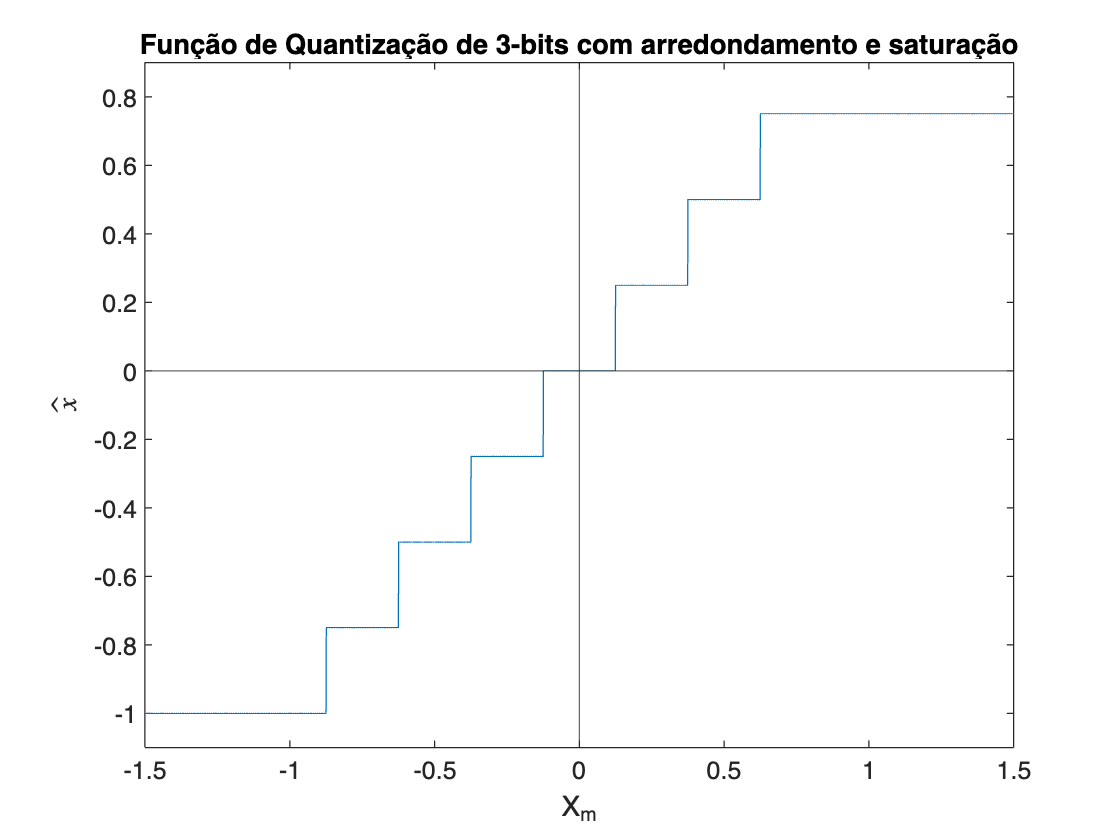


x= -2:0.001:2;
quant = fxquant(x,3,'round','sat');
plot(x,quant);
title('Função de Quantização de 3-bits com arredondamento e saturação');
yline(0); xline(0);
xlabel('X_m'); ylabel('$$\hat{x}$$','Interpreter','Latex')
axis([-1.5 1.5 -1.1 0.9]);


deltaQaunt = max(x)*1/2^3

deltaQaunt = 0.2500

O valor de $\Delta$ para esse quantizador é de 0,25, dado como o passo de quantização para 3 bits e o sinal de amplitude -2 a 2. Para um erro de quantização que satisfaça (2 -2), o sianl x deverá ser de no máximo $\pm$15. 

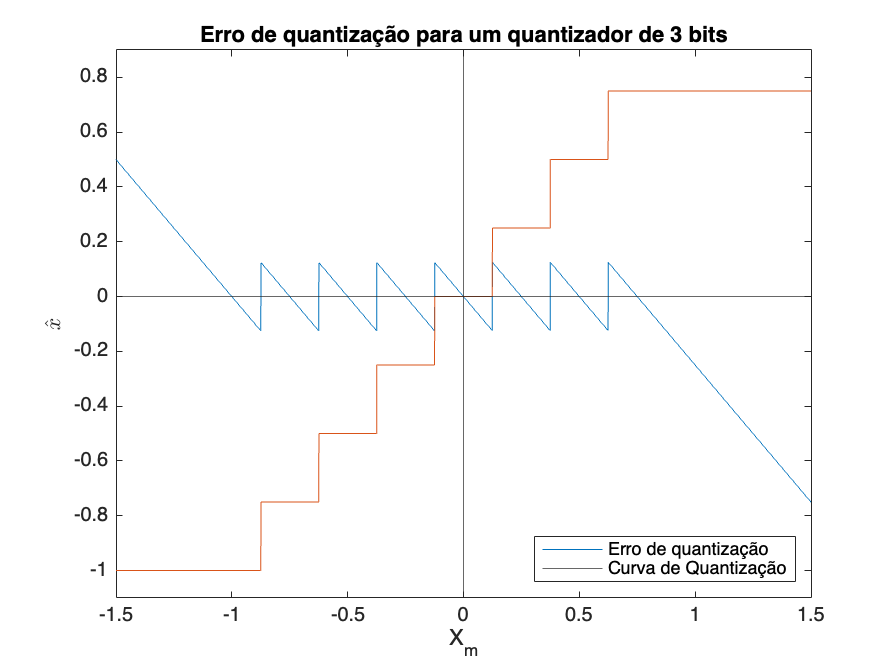

quant_2 = fxquant(x,3,'round','sat')-x;
plot(x,quant_2);
title('Erro de quantização para um quantizador de 3 bits');
yline(0); xline(0);
xlabel('X_m'); ylabel('$$\hat{x}$$','Interpreter','Latex')
axis([-1.5 1.5 -1.1 0.9]);
hold on
plot(x,quant);
legend('Erro de quantização','Curva de Quantização');
legend('Location','southeast');
hold off

O Gráfico descreve o erro total de um quantizador de 3 bits. Dentro da faixa normal de operação, o erro total será de $\pm$$\Delta$. Ao atingir a faixa de saturação, o quantizador deixa de descrever as variações do sinal e será diretamente proporcional ao desvio da faixa máxima de quantização, posto que o erro é linear.

## Exercício 2.2

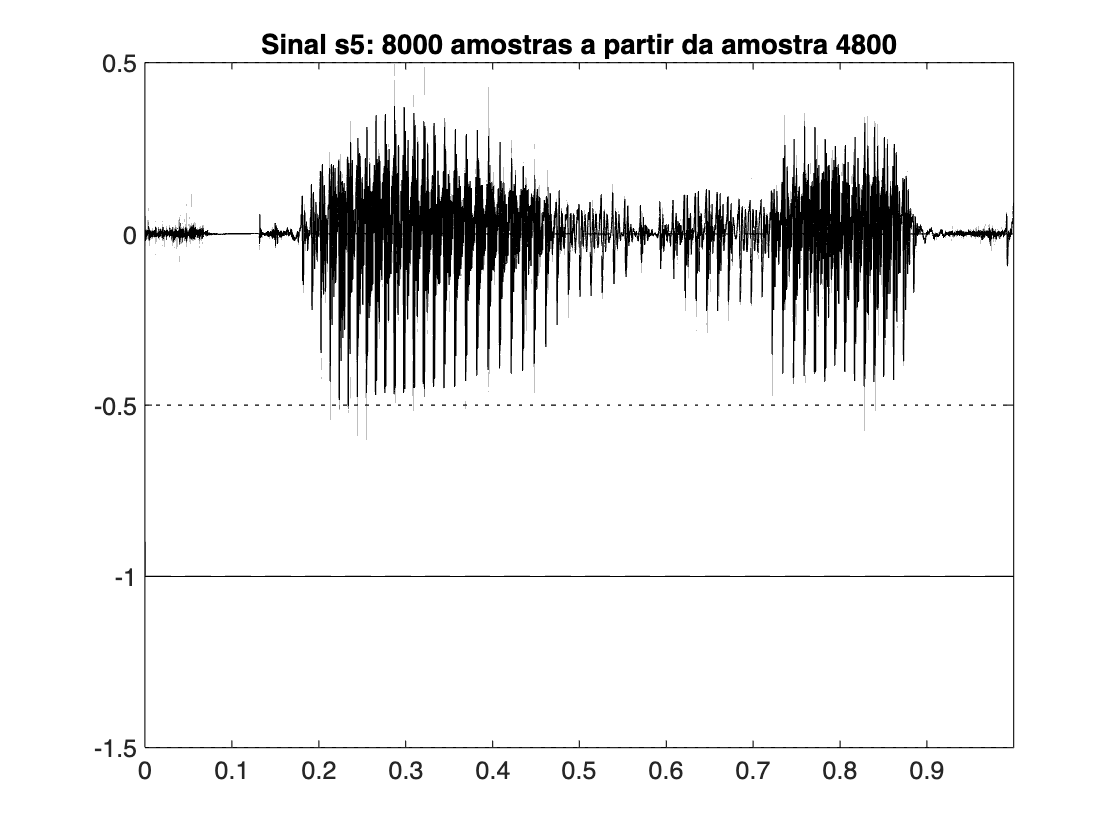

posInicio=0.6*8000; %posição de onde serão retiradas as 8k amostras, arbitrário
nAmostras=8000;

trecho_s5 = s5(posInicio:posInicio+nAmostras);
striplot(trecho_s5,8000,nAmostras);
titulo=sprintf("Sinal s5: %d amostras a partir da amostra %d",nAmostras,posInicio);
title(titulo);

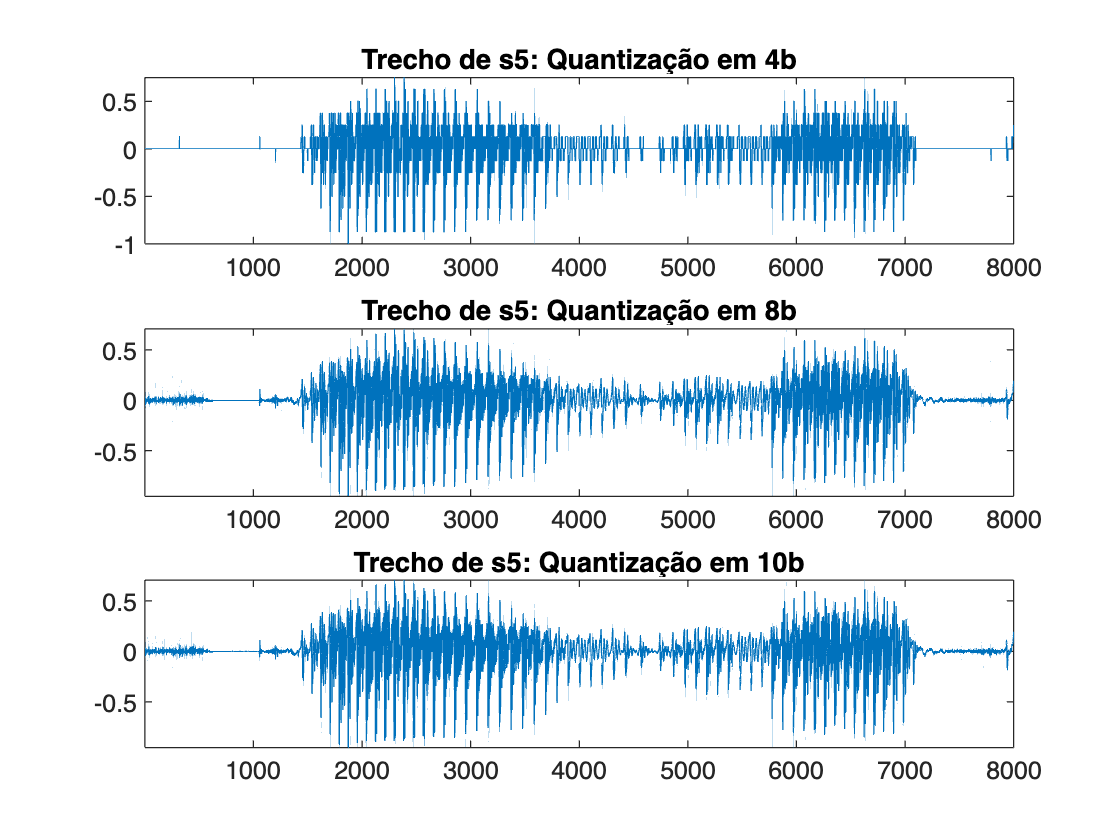


s5_quant_10b =fxquant(trecho_s5,10,'round','sat');
s5_quant_8b =fxquant(trecho_s5,8,'round','sat');
s5_quant_4b =fxquant(trecho_s5,4,'round','sat');

figure
subplot(3,1,1)
plot(s5_quant_4b);
axis tight;
title("Trecho de s5: Quantização em 4b");

subplot(3,1,2)
plot(s5_quant_8b);
axis tight;
title("Trecho de s5: Quantização em 8b");

subplot(3,1,3)
plot(s5_quant_10b);
axis tight;
title("Trecho de s5: Quantização em 10b");

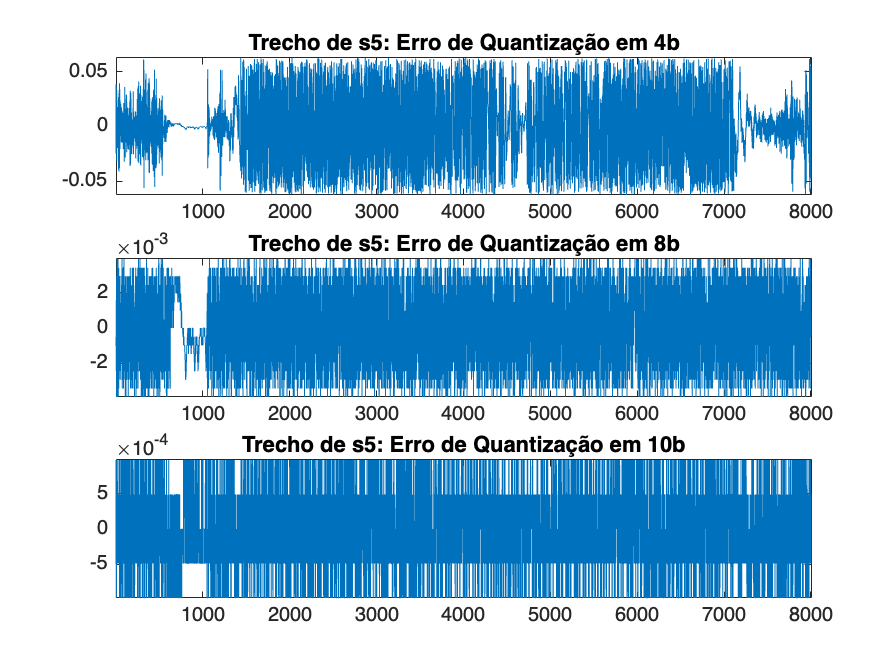



erro_s5_quant_10b =fxquant(trecho_s5,10,'round','sat')-trecho_s5;
erro_s5_quant_8b =fxquant(trecho_s5,8,'round','sat')-trecho_s5;
erro_s5_quant_4b =fxquant(trecho_s5,4,'round','sat')-trecho_s5;

figure
subplot(3,1,1)
plot(erro_s5_quant_4b);
axis tight;
title("Trecho de s5: Erro de Quantização em 4b");

subplot(3,1,2)
plot(erro_s5_quant_8b);
axis tight;
title("Trecho de s5: Erro de Quantização em 8b");

subplot(3,1,3)
plot(erro_s5_quant_10b);
axis tight;
title("Trecho de s5: Erro de Quantização em 10b");

## Exercício 2.3

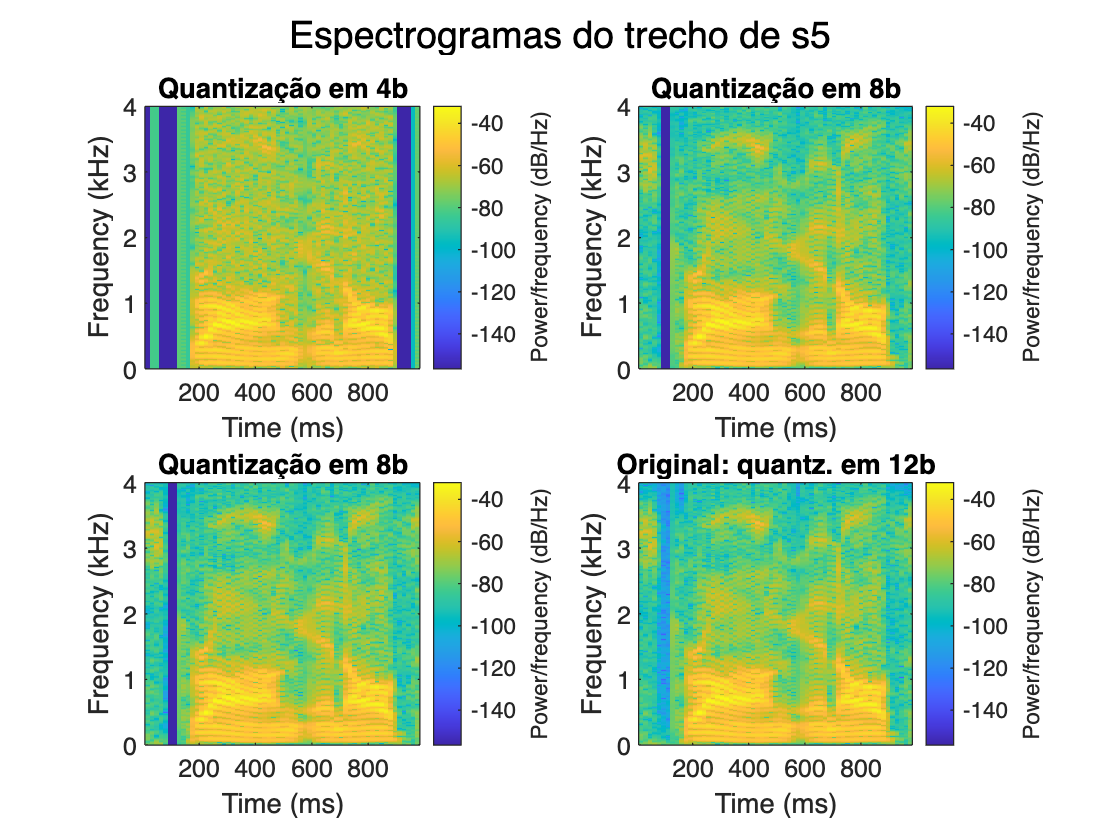

 janela = hamming(256);
 f=0:1:4000;

figure
subplot(2,2,1);
spectrogram(s5_quant_4b, janela,[],f,8000,'yaxis'); 
 title("Quantização em 4b");

subplot(2,2,2);
spectrogram(s5_quant_8b, janela,[],f,8000,'yaxis'); 
title("Quantização em 8b");

subplot(2,2,3);
spectrogram(s5_quant_8b, janela,[],f,8000,'yaxis'); 
title("Quantização em 8b");

subplot(2,2,4);
spectrogram(trecho_s5, janela,[],f,8000,'yaxis'); 
title("Original: quantz. em 12b");

sgtitle('Espectrogramas do trecho de s5');